# Plots

Medianen er det midterste data punkt i et ordnede data sæt.

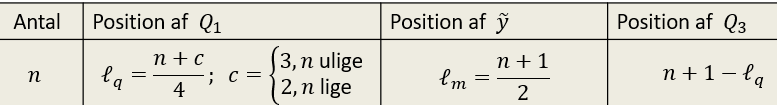

Hvis 2 tal er fundet som median tage gennemsnittet af disse

## Box plots

et **step ** er $1,5 \cdot (Q_3 - Q_1)$

Lower inner fence(LIF)


$$LIF = Q_1 - step$$


Upper inner fence(UIF)


$$UIF = Q_3 + step$$


Bogens metode -- andre steder kan man også bruge min og maximum værdien.

       mindste observation ≥LIF og 

       største observation ≤UIF

Det der er uden for dette er outliers

md =                        9.5


q1 =      5


q3 =     16


Q =                          5                       9.5                        16


Q =                          5                       9.5                        16


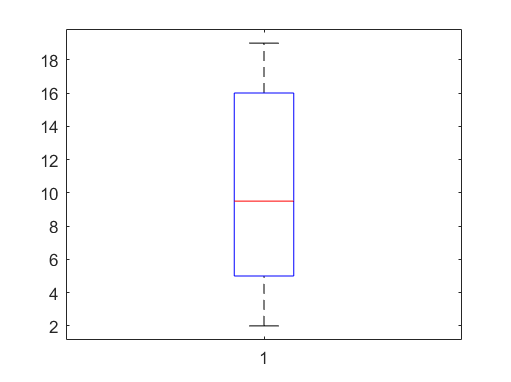

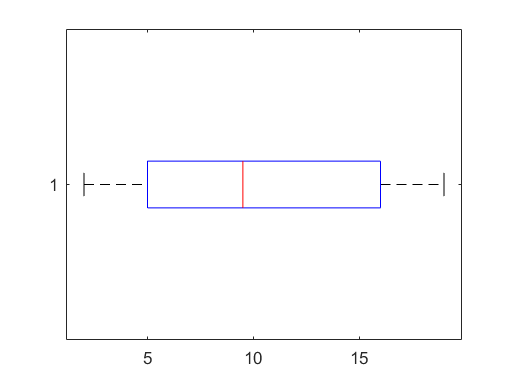

figure(1)
X = [2 3 5 7 9 10 15 16 16 19]; %data sættet
y_bar = mean(X)
md = median(X); % finder medianen
q1 = prctile(X, 25); % finder første kvatil ved at finde data punkt ved 25%
q3 = prctile(X, 75); % finder første kvatil ved at finde data punkt ved 75%
Q = prctile(X, [25, 50, 75]); % finder alle 3 kvatiler ud fra 25% 50% 75% Q2 = medianen
Q = quantile(X, 3); % finder alle 3 kvatiler ud fra procent

boxplot(X,'Orientation',"horizontal")
xline(y_bar, '--', color='g', DisplayName='Stikprøvens middelværdi')
xlabel('W')
legend('location', 'northeastoutside')
grid("on")

**forklaring fra anden data**

Boxplottet har en median på 101.5, som stort set er sammenfaldende med middelværdien på 101.4.

Det interkvartile range ligger pænt symmetrisk omkring medianen. Med nedre kvartil på 98.5 og øvre kvartil på 105.0. Den øvre del er lidt bredere end den nedre del.

Den nedre kost er lidt længere end den øvre. Dvs. fordelingen af data er lidt venstre skæv.

Der er ingen outliers.

Dvs. data kommer fra en stort set pæn fordeling

Eksempel

clear
data = xlsread("Eksamens sæt\18E\Data_M4STI1_2018E.xlsx");
bat1 = data(1:5,4)

bat1 =        11453
        8850
       10451
        8317
       10915


bat2 = data(6:10,4)

bat2 =         9027
        9794
        7493
        9204
        8319


bat3 = data(11:15,4)

bat3 =        10030
        8968
       10679
       11446
       10433


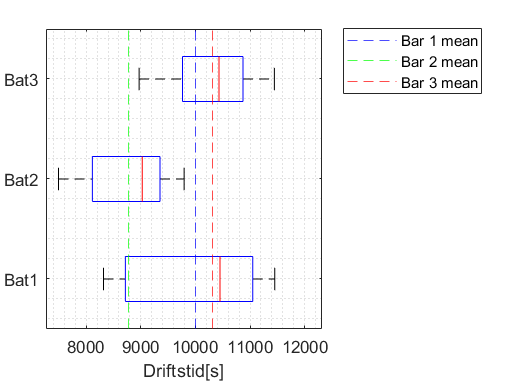


boxplot(data(1:15,4),data(1:15,3), 'Orientation','horizontal', ...
     "Labels", {'Bat1', 'Bat2', 'Bat3'})
xline(mean(bat1), '--b', 'DisplayName', 'Bar 1 mean')
xline(mean(bat2), '--g', 'DisplayName', 'Bar 2 mean')
xline(mean(bat3), '--r', 'DisplayName', 'Bar 3 mean')
xlabel('Driftstid[s]')
legend('location', 'northeastoutside')
grid("minor")

## Mere atomatiserede

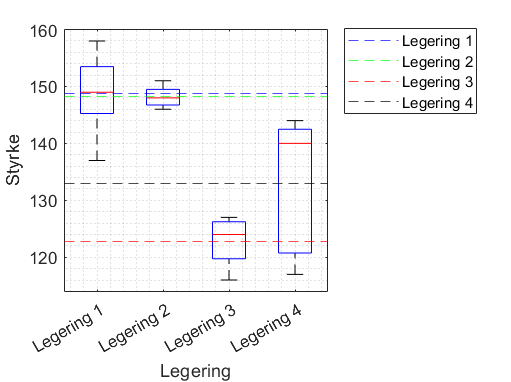

data = xlsread('M4STI_2015_data.xlsx');

n_start = 1; %første række af datapunkter
n_slut = 20; % sidste rækker af data
n_treat = 5; % antal data per forsøg
col = 4; % collonnen dataen er i
treatment = 3; % hvilket forsøg dataen tilhøre

labels = {'Legering 1', 'Legering 2', 'Legering 3', 'Legering 4'};


boxplot(data(n_start:n_slut,col), data(n_start:n_slut,treatment), ... % 'Orientation','horizontal',
         "Labels", labels)
colors = {'--b', '--g', '--r', '--k'};

for i = n_start:n_slut/n_treat
    yline(mean(data(n_start:n_start + n_treat - 1, col)), string(colors(i)), 'DisplayName', string(labels(i)))
    n_start = n_start + n_treat;
end

ylabel('Styrke')
xlabel('Legering')
legend('location', 'northeastoutside')
grid("minor")

## Histogram

M = 4
hist(data(:,4),M) % her data datasættet og M er hvor mange bar der ønskes i histogramemt  

eller

% histogram(sol_celle_data, [90:5:110])

Histogrammet viser, at data kommer fra en pæn fordeling med en enkelt top, lidt venstre skæv og med hurtigt uddøende haler.

Plot med navngivning af bar, her skal bins være lige så stor som data sættet

data = [35, 189, 376, 220, 30];
bins = categorical({'150', '150-200','200-250', '250-300','300'});% 1:length(data);%
bar(bins, data)

## Areal under kurve

clear
mu = 0.45

mu = 0.4500

Y = linspace(0,2.5,100);
y = 1

y = 1

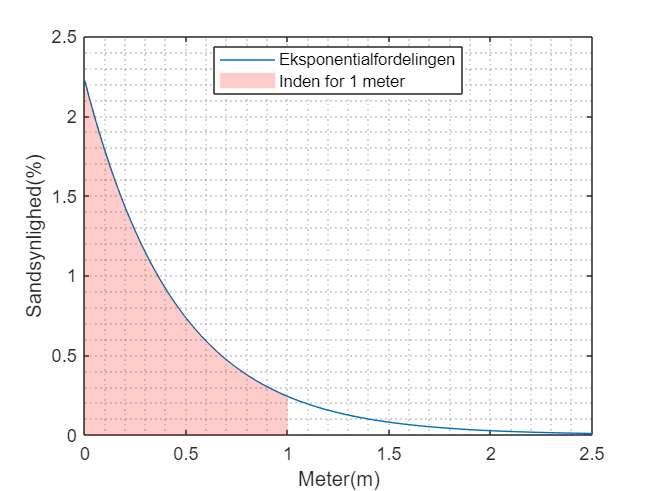


P = exppdf(Y, mu);
plot(Y, P,'DisplayName', 'Eksponentialfordelingen')
hold on
% xline(y, 'r--', DisplayName="Inden for " + y + " meter")
ylabel('Sandsynlighed(%)')
xlabel('Meter(m)')
legend('location', 'best')%, 'northeastoutside')
grid("minor")


%%%%%%%%  kode til areal under kuve  %%%%%
x = [0:0.1:y];
a1 = area(x,exppdf(x, mu),  ...
    DisplayName="Inden for " + y + " meter",  ...
    facecolor='r', ...
    EdgeColor='none'); % 'HandleVisibility','off',
alpha(a1, 0.2);

hold off

## Scatter plots

T = data(1:22,7);
S = data(1:22,9);

figure(4)
scatter(T, S, DisplayName='Temperatur data')
lsline
xlabel('Temperatur-T')
ylabel('Styrke-S')
grid('minor')
legend('Location','best')

## Fitlm plot

T = data(1:22,7);
S = data(1:22,9);
mdl_T = fitlm(T,S);
plot(mdl_T)

% eller
mdl2 = fitlm([T, p],S, 'y ~ x1 + x2 + x1^2 + x2^2 + x1:x2') % til en anderledes model

Med udvidelse

## Normal plot

normplot(data)

**eksempel på forklaring**

Normalfordelingsplottet viser en pæn lineær sammenhæng. Dette støtter antagelsen om en pæn fordeling, dvs. at stikprøvens fordeling ligner en normalfordeling.

## Stem n leaf plot

stemleafplot(data, p)

p er fx -1 det er hvor store enheder der vises i.

## Residualer og outliers

lev = mdl4.Diagnostics.Leverage; %løfte punkter %'unormale' i x-retningen
rst = mdl4.Residuals.Studentized; % Outlier punkter "unormale" værdier i y-retningen. abs(rst) skal gerne være mindre end 3


c = 3; %antal regressor variable
n = length(rst); %antalt observationer
lev_limit = 2 * (c +1 )/ n
find(lev > lev_limit)

Punkterne 2, 12 og 22 er således størrer en vores grænse på 0,36364 og er dermed løfte punbkter

find(abs(rst) > 3)

Der findes ingen residualer der er størrer end 3 og dermed ingen outliers

Et punkt skal være både et løftestangspunkt og outlier for at være et indflydelsespunkt. Der er derfor ingen indflydelsespunkter.

nr = (1:length(S))';
disp(table(nr, T, p, S, lev, rst))